clear; close all; clc;
syms V_sc C_L C_D_0 A e W2S rho r g

C_L_max = 2.7;
b = 20;
W_MGTO = 9690; % Maximum Gross Takeoff Weight (N) (our aircraft)

assume(A,'positive'); assume(e,'positive'); assume(V_sc,'positive'); assume(rho,'positive');
assume(C_L,'positive'); assume(C_D_0,'positive'); assume(r,'positive'); assume(g,'positive');

cos_phi = sqrt(1 - (2*W2S./(rho*r*g*C_L)).^2)

$$cos\_phi = \sqrt{1-\frac{4\,{\mathrm{W2S}}^{2}}{{C_{L}}^{2}\,g^{2}\,r^{2}\,\rho^{2}}}$$

C_D = (C_D_0 + C_L.^2 ./ (pi*A.*e));
eqn = V_sc == C_D * (C_L * cos_phi).^(-3/2) * sqrt(2 * W2S / rho);

%eqn = V_sc == SinkRateCircle(C_L, C_D_0, A, e, W2S, rho, r)
wingLoading = solve(eqn, W2S,"ReturnConditions",true)

wingLoading = struct with fields:
           W2S: [6×1 sym]
    parameters: [1×0 sym]
    conditions: [6×1 sym]



wingLoading_Realified = wingLoading.W2S .* (1-heaviside(abs(imag(wingLoading.W2S))))


wingloading_pos_real = wingLoading.W2S(1);
wingLoading_Realified = wingloading_pos_real

$$wingLoading\_Realified = \frac{A^{2}\,{C_{L}}^{3}\,{V_{\mathrm{sc}}}^{2}\,e^{2}\,\rho \,\pi^{2}\,{\mathrm{root}\left(A^{4}\,{C_{L}}^{4}\,{V_{\mathrm{sc}}}^{4}\,e^{4}\,z^{6}\,\pi^{4}+4\,\pi \,A\,C_{D,0}\,{C_{L}}^{6}\,e\,g^{2}\,r^{2}\,z^{2}+4\,A^{3}\,{C_{D,0}}^{3}\,{C_{L}}^{2}\,e^{3}\,g^{2}\,r^{2}\,z^{2}\,\pi^{3}+6\,A^{2}\,{C_{D,0}}^{2}\,{C_{L}}^{4}\,e^{2}\,g^{2}\,r^{2}\,z^{2}\,\pi^{2}+A^{4}\,{C_{D,0}}^{4}\,e^{4}\,g^{2}\,r^{2}\,z^{2}\,\pi^{4}+{C_{L}}^{8}\,g^{2}\,r^{2}\,z^{2}-4\,\pi \,A\,C_{D,0}\,{C_{L}}^{6}\,e\,g^{2}\,r^{2}-4\,A^{3}\,{C_{D,0}}^{3}\,{C_{L}}^{2}\,e^{3}\,g^{2}\,r^{2}\,\pi^{3}-6\,A^{2}\,{C_{D,0}}^{2}\,{C_{L}}^{4}\,e^{2}\,g^{2}\,r^{2}\,\pi^{2}-A^{4}\,{C_{D,0}}^{4}\,e^{4}\,g^{2}\,r^{2}\,\pi^{4}-{C_{L}}^{8}\,g^{2}\,r^{2},z,1\right)}^{3}}{2\,{\left({C_{L}}^{2}+\pi \,A\,C_{D,0}\,e\right)}^{2}}$$


% test out the solutions

% define the sink rates given in the spec
V_sc_threshold = convvel(250,"ft/min","m/s"); % threshold
V_sc_objective = convvel(175,"ft/min","m/s"); % objective

% get values ready to be substitued in 
values = {g, rho, r, C_D_0, e, C_L, V_sc}; % List of variables to substitute
subs_values = {9.81, 1.0834, convlength(250,"ft","m"), 0.0075, 0.9, C_L_max, V_sc_threshold}; % Corresponding values for the variables
% substitue the values
eqn_substituted = subs(wingLoading_Realified, values, subs_values)

$$eqn\_substituted = \frac{139297264808139\,A^{2}\,\pi^{2}\,{\mathrm{root}\left(5805236967952288262400\,A^{4}\,z^{6}\,\pi^{4}+74240864901989361\,A^{4}\,z^{2}\,\pi^{4}+374088433629659287696128000\,\pi \,A\,z^{2}+519567268930082344022400\,A^{2}\,z^{2}\,\pi^{2}+320720536376594039520\,A^{3}\,z^{2}\,\pi^{3}+101003877080008007677954560000\,z^{2}-519567268930082344022400\,A^{2}\,\pi^{2}-320720536376594039520\,A^{3}\,\pi^{3}-74240864901989361\,A^{4}\,\pi^{4}-374088433629659287696128000\,\pi \,A-101003877080008007677954560000,z,1\right)}^{3}}{10000000000000\,{\left(\frac{27\,\pi \,A}{4000}+\frac{729}{100}\right)}^{2}}$$


% produce output

% I suspect only the first two solutions are real and only the first to be
% real and positive - this is true thus far
Aspects = linspace(1,50,100);
W2S_found = double((subs(eqn_substituted,"A",Aspects)))

W2S_found =     2.5719    5.7313   10.1247   15.7397   22.5625   30.5766   39.7619   50.0939   61.5419   74.0686   87.6286  102.1675  117.6218  133.9187  150.9758  168.7029  187.0027  205.7728  224.9080  244.3023  263.8515  283.4555  303.0201  322.4588  341.6937  360.6566  379.2888  397.5415  415.3751  432.7586  449.6689  466.0902  482.0126  497.4317  512.3474  526.7635  540.6867  554.1262  567.0931  579.6000  591.6603  603.2884  614.4990  625.3071  635.7276  645.7756  655.4657  664.8123  673.8296  682.5311


%g = 9.81; r = convlength(250,"ft","m"); C_L = 2.7; g^2*r^2*(C_L^2 + A*C_D_0*e*pi).^4
plot(W2S_found,Aspects);

hold on

subs_values = {9.81, 1.0834, convlength(250,"ft","m"), 0.0075, 0.9, C_L_max, V_sc_objective}; % Corresponding values for the variables
% substitue the values
eqn_substituted = subs(wingLoading_Realified, values, subs_values)

$$eqn\_substituted = \frac{6825565975598811\,A^{2}\,\pi^{2}\,{\mathrm{root}\left(34845934900133610295056\,A^{4}\,z^{6}\,\pi^{4}+8018013409414850988000\,A^{3}\,z^{2}\,\pi^{3}+12989181723252058600560000\,A^{2}\,z^{2}\,\pi^{2}+1856021622549734025\,A^{4}\,z^{2}\,\pi^{4}+9352210840741482192403200000\,\pi \,A\,z^{2}+2525096927000200191948864000000\,z^{2}-12989181723252058600560000\,A^{2}\,\pi^{2}-1856021622549734025\,A^{4}\,\pi^{4}-9352210840741482192403200000\,\pi \,A-8018013409414850988000\,A^{3}\,\pi^{3}-2525096927000200191948864000000,z,1\right)}^{3}}{1000000000000000\,{\left(\frac{27\,\pi \,A}{4000}+\frac{729}{100}\right)}^{2}}$$


% produce output

% I suspect only the first two solutions are real and only the first to be
% real and positive - this is true thus far
Aspects = linspace(1,50,100);
W2S_found = double((subs(eqn_substituted,"A",Aspects)))

W2S_found =     1.2603    2.8084    4.9616    7.7143   11.0610   14.9959   19.5127   24.6048   30.2646   36.4839   43.2533   50.5624   58.3992   66.7502   75.6003   84.9324   94.7278  104.9654  115.6224  126.6736  138.0923  149.8497  161.9155  174.2579  186.8440  199.6402  212.6122  225.7258  238.9468  252.2417  265.5780  278.9242  292.2505  305.5286  318.7324  331.8374  344.8217  357.6652  370.3500  382.8606  395.1832  407.3063  419.2201  430.9166  442.3895  453.6339  464.6463  475.4245  485.9673  496.2747


%g = 9.81; r = convlength(250,"ft","m"); C_L = 2.7; g^2*r^2*(C_L^2 + A*C_D_0*e*pi).^4
plot(W2S_found,Aspects);

% confirm which region is acceptable
V_sc_ul_ftmin = convvel(SinkRateCircle(C_L_max, .0075, 30, .9, 200, 1.0834, convlength(250,"ft","m")),"m/s","ft/min") % sink rate in upper left region in ft/min

V_sc_ul_ftmin = 81.7264

V_sc_lr_ftmin = convvel(SinkRateCircle(C_L_max, .0075, 10, .9, 800, 1.0834, convlength(250,"ft","m")),"m/s","ft/min")% sink rate in lower right region in ft/min

V_sc_lr_ftmin = 803.9742

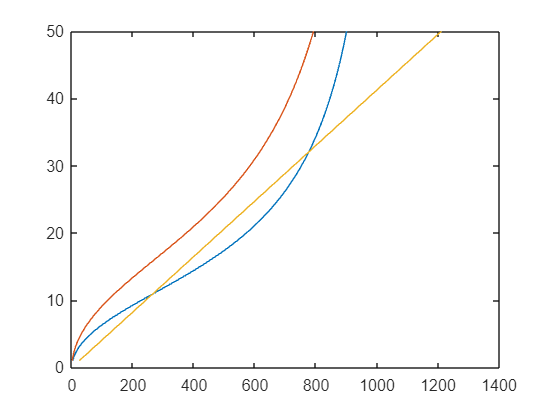


S_possible = b^2 ./ Aspects;
W2S_possible = W_MGTO ./ S_possible;
plot(W2S_possible, Aspects);